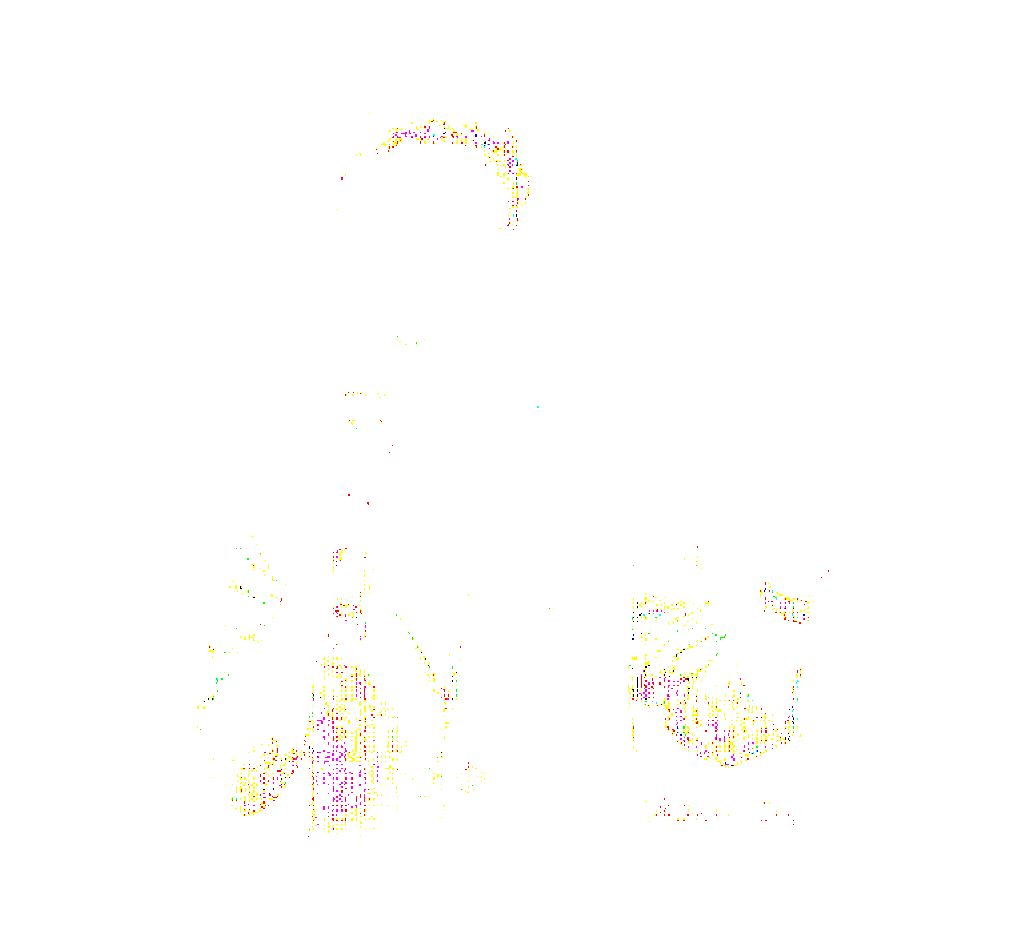

image=imread('me.png');
zoom=2;

[r,c,d]=size(image);

rn = floor(zoom*r);
cn = floor(c*zoom);

s=zoom;
im_zoom=zeros(rn,cn,d);
for i =1:rn
    x1=cast(floor(i/s),'uint32');
    x2=cast(ceil(i/s),'uint32');
    if x1==0
        x1=1;
    end
    for j=1:cn
        y1=cast(floor(j/s),'uint32');
        y2=cast(ceil(j/s),'uint32');
        if y1==0
            y1=1;
        end
   ctl = image(x1,y1,:);
cbl = image(x2,y1,:);
ctr = image(x1,y2,:);
cbr = image(x2,y2,:);
y = rem(j/s,1);
tr = (ctr*y)+(ctl*(1-y));
br = (cbr*y)+(cbl*(1-y));
im_zoom(i,j,:) = (br*x)+(tr*(1-x));
end
end
imshow(im_zoom);